[sig,fs]=audioread('vinyl1.wav')

sig =     0.0009
    0.0008
    0.0009
    0.0010
    0.0012
    0.0011
    0.0009
    0.0009
    0.0009
    0.0005


fs = 44000

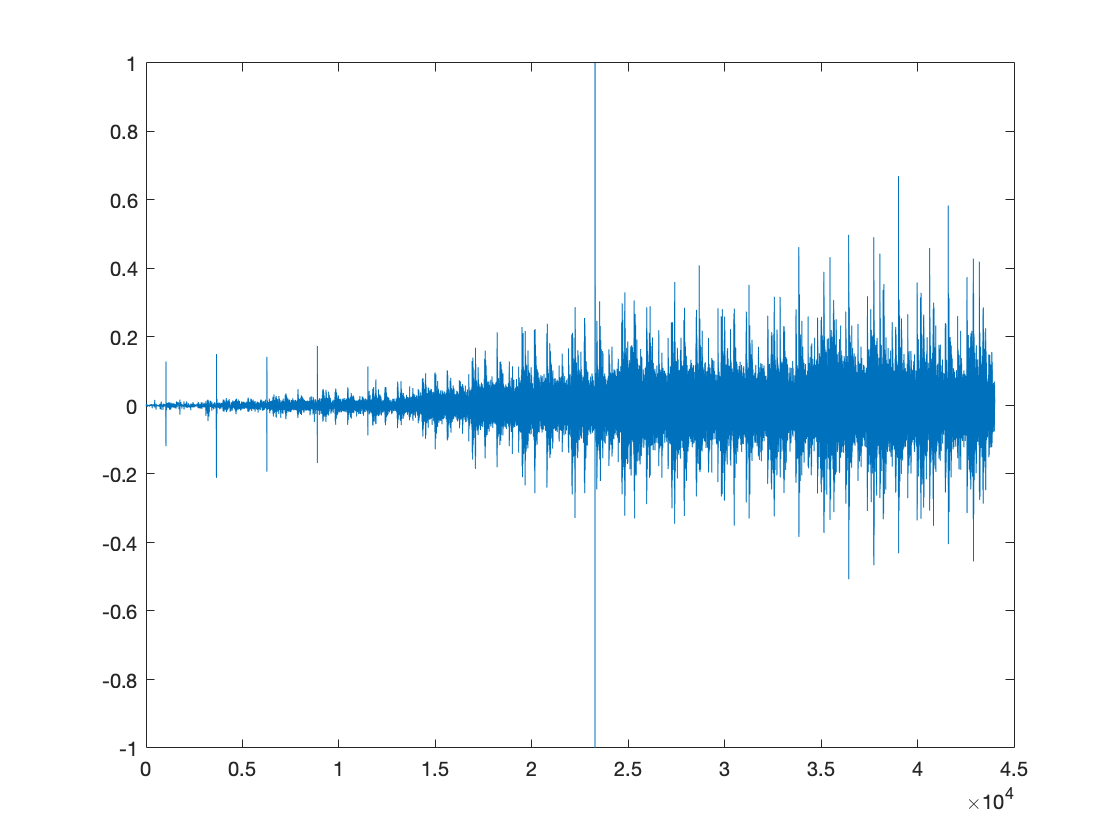

%sig=ans;

f=((0:length(sig)-1)*fs)/length(sig);
plot(f,sig)

ffsig=fft(sig)

ffsig = 	1.0e+03 *

  -0.0563 + 0.0000i
   0.0295 - 0.0029i
  -0.0205 + 0.0103i
   0.0269 - 0.0137i
  -0.0158 + 0.0180i
   0.0186 - 0.0194i
  -0.0073 + 0.0232i
   0.0115 - 0.0266i
   0.0024 + 0.0266i
   0.0024 - 0.0278i


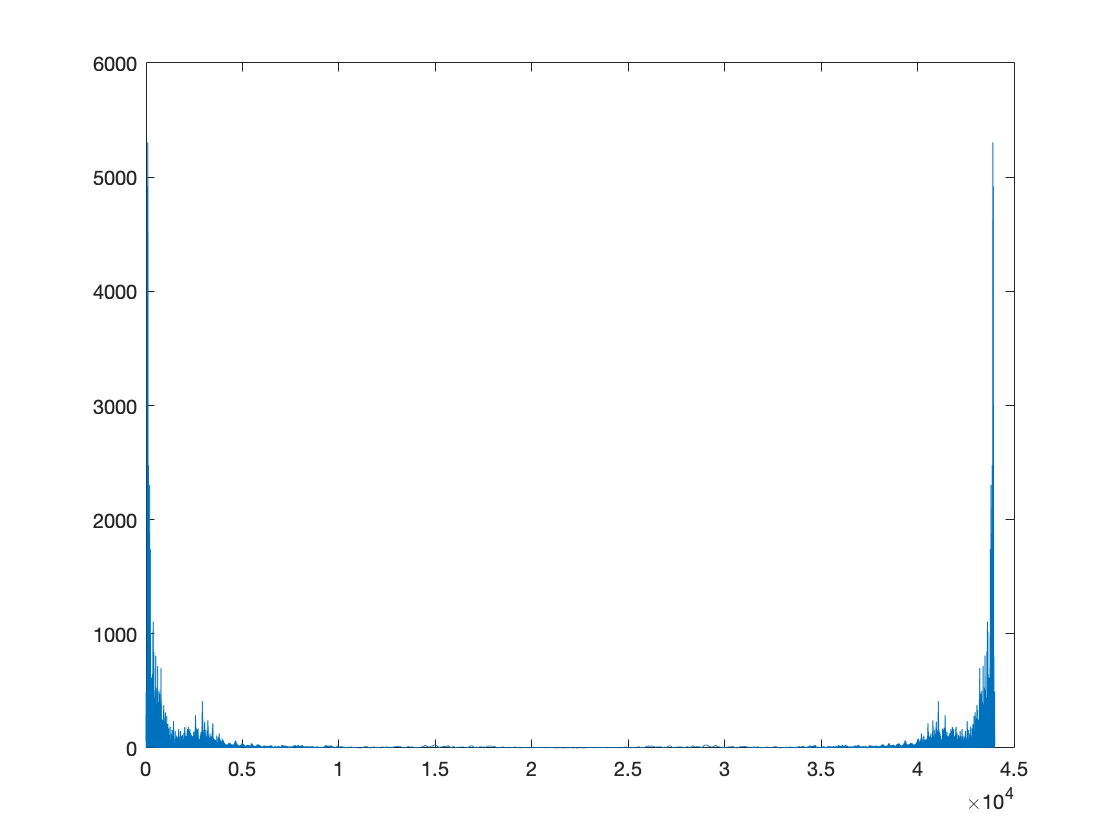

plot(f,abs(ffsig));

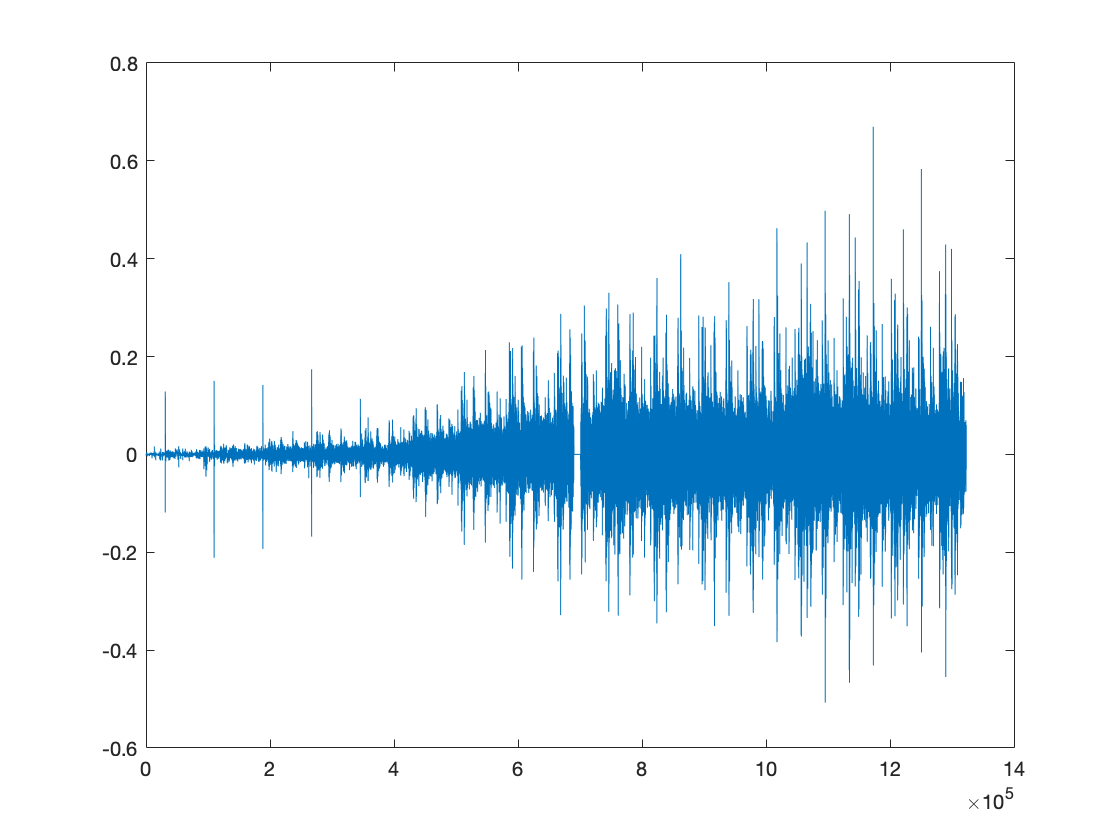


%[x,peak]=max(sig);

filtsig = sig; 
%filtsig=sig;
filtsig(6.9*10^5:7.01*10^5) = 0;
%filtsig([1:peak, end-peak:end]) = 0;


plot(filtsig);

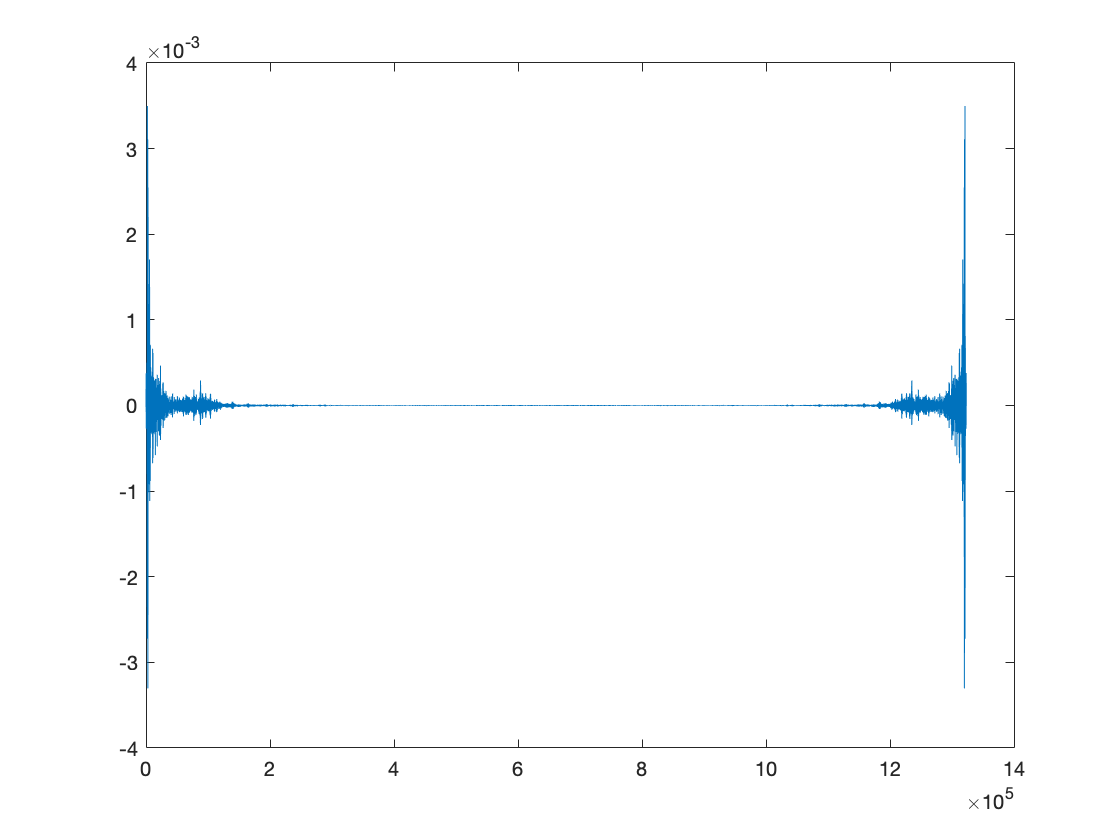


sigir=real(ifft(filtsig));
figure
plot(sigir);


%y = medfilt1(sig);
%plot(y)


Question 7.2

clear

[sig]=audioread('vinyl1.wav')

sig =     0.0009
    0.0008
    0.0009
    0.0010
    0.0012
    0.0011
    0.0009
    0.0009
    0.0009
    0.0005


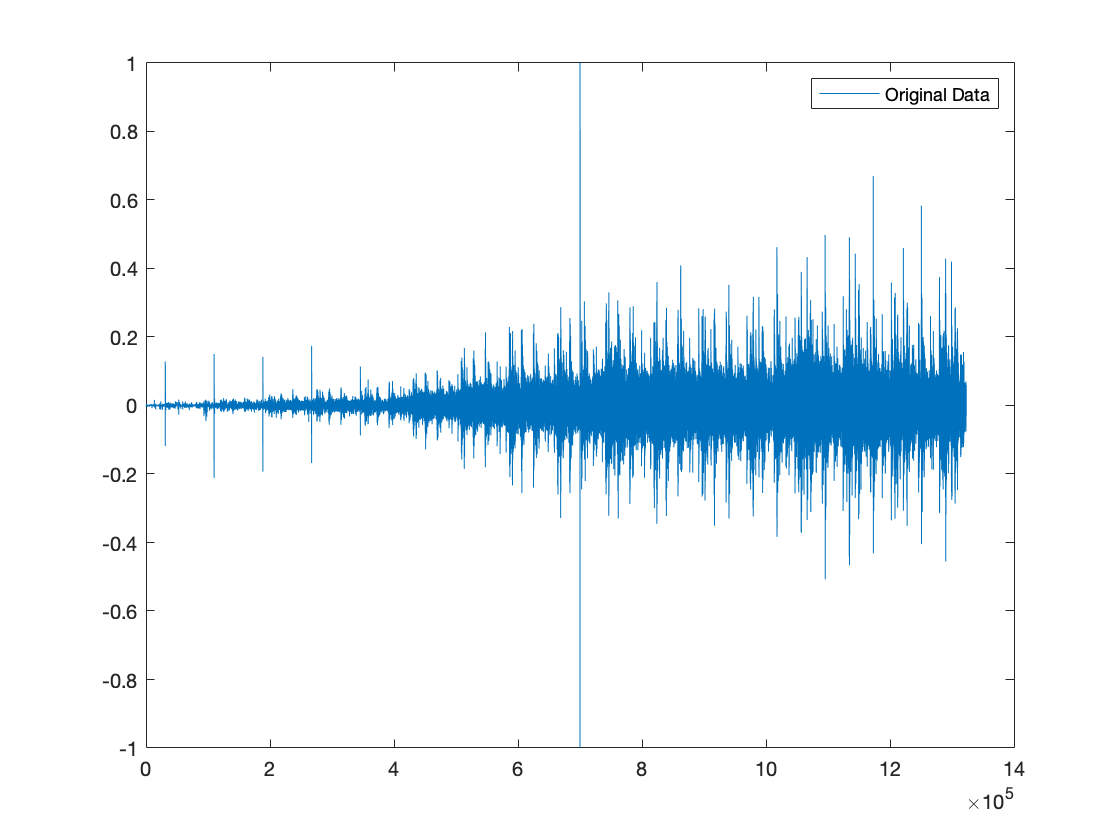


a=1;
t = 1:length(sig);

b10=1/10*ones(1,10);
b100=1/100*ones(1,100);
b1000=1/1000*ones(1,1000);


y10=filter(b10,a,sig);
y100=filter(b100,a,sig);
y1000=filter(b1000,a,sig);

plot(t,sig)
legend('Original Data')

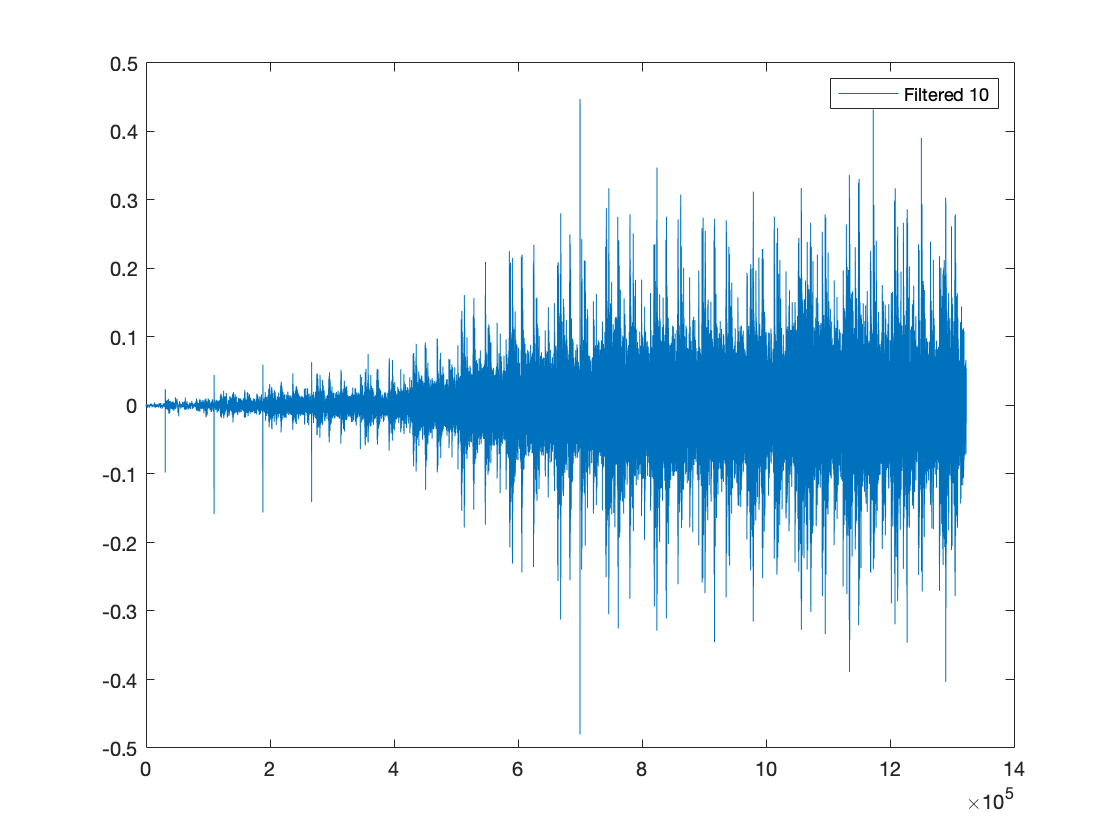


plot(t,y10)
legend('Filtered 10')

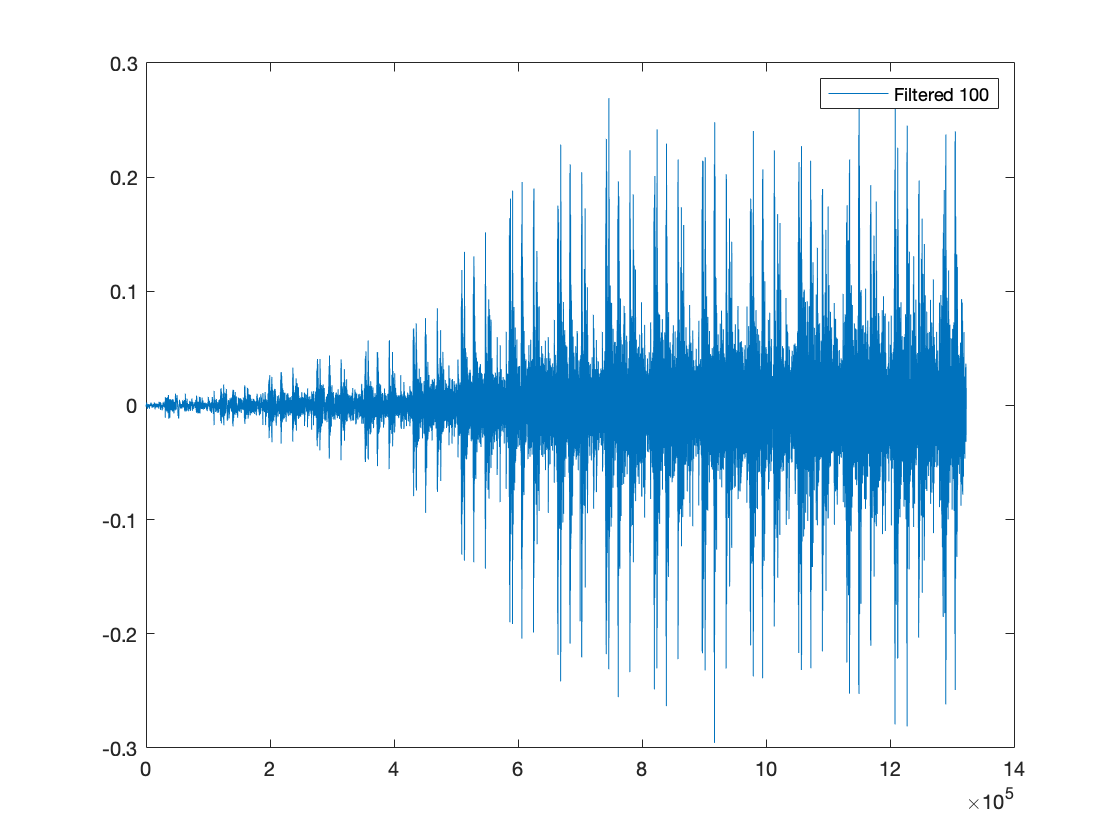


plot(t,y100)
legend('Filtered 100')

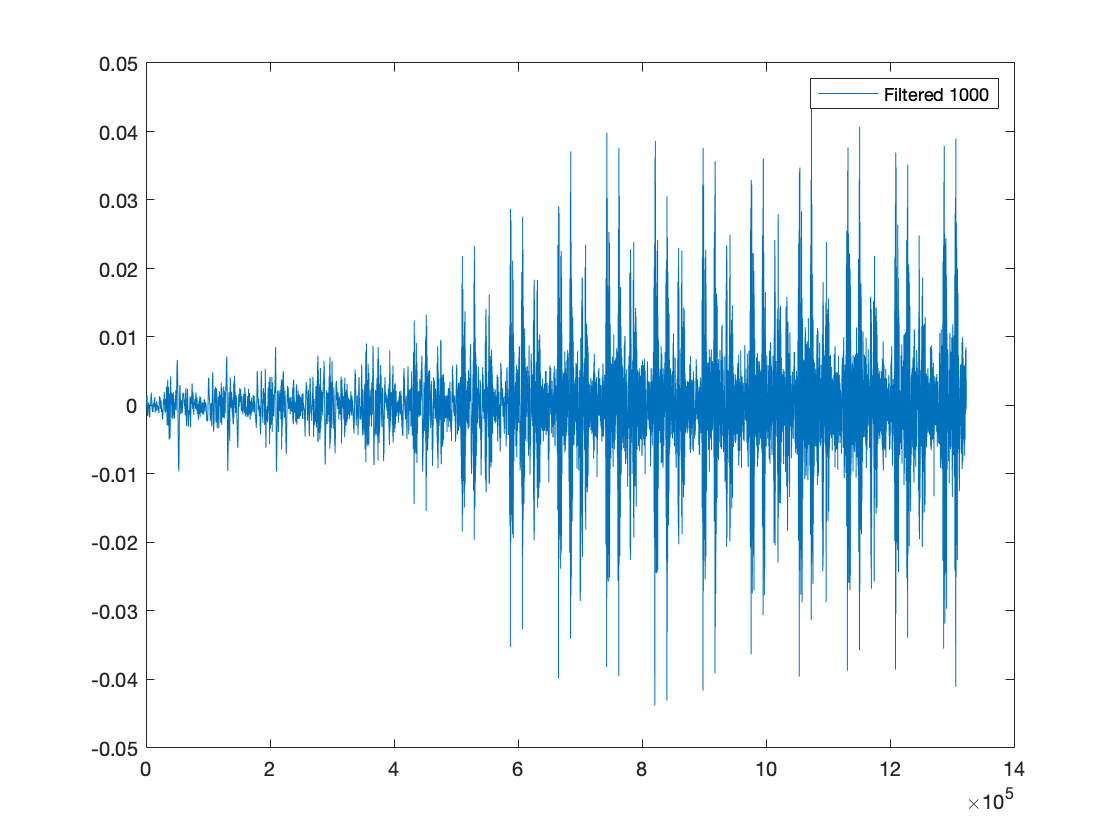


plot(t,y1000)
legend('Filtered 1000')

Question 3

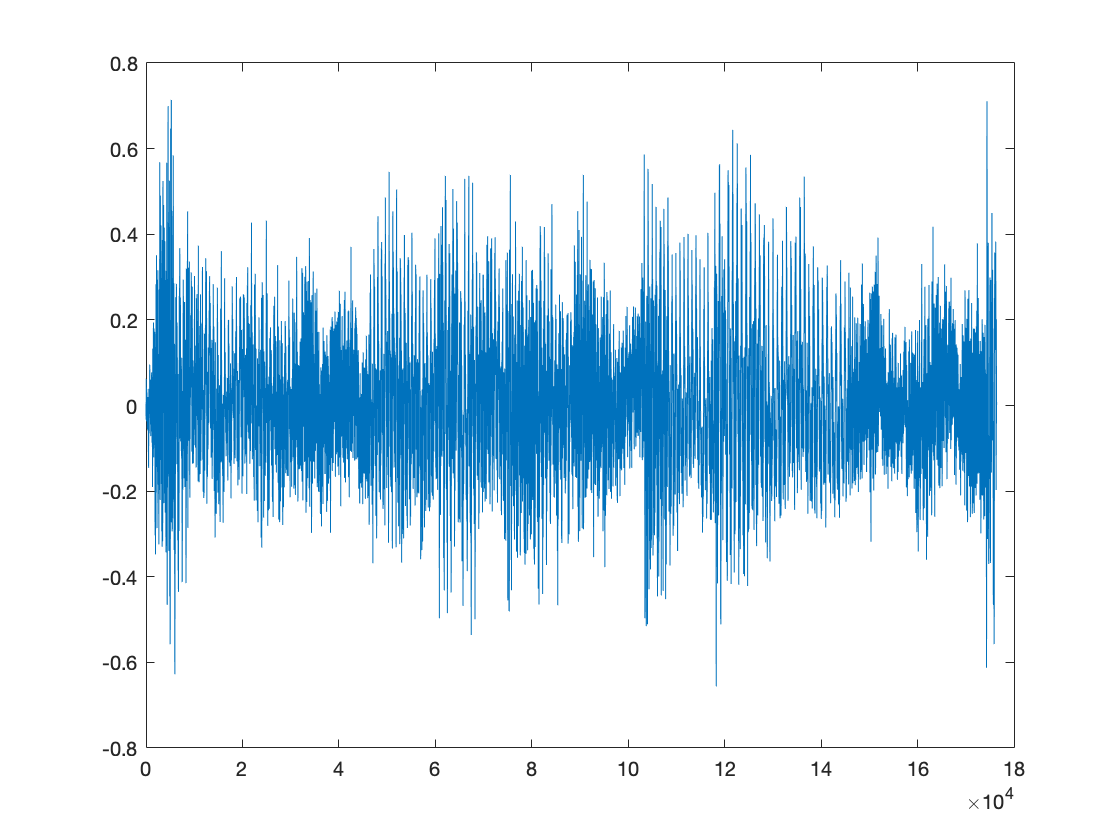

clear
[sig,fs]=audioread('cd1.wav');

sig=sig(:)';

c=[1/sqrt(2),1/sqrt(2)];
d=[-1/sqrt(2),1/sqrt(2)];

[a1,b1]=dwlt(sig,c,d);
[a2,b2]=dwlt(a1,c,d);
[a3,b3]=dwlt(a2,c,d);

%C1 = wldecom(v,3,c,d);
N=length(b1)+length(b2)+length(b3);

sigma=mad(b1,1)/0.6745;
lambda=sigma*sqrt(2*log(N));

b1s=softThresholding(b1,lambda);
b2s=softThresholding(b2,lambda);
b3s=softThresholding(b3,lambda);

%S=softThresholding(Cb,lambda);
% a3=a3(:)';
% b3s=b3s(:)';
% b2s=b2s(:)';
% b1s=b1s(:)';
a22 = idwlt(a3,b3s,c,d);
a11 = idwlt(a22,b2s,c,d);
rec_sig = idwlt(a11,b1s,c,d);

figure
plot(rec_sig);


audiowrite('cd3.wav',rec_sig,fs);


%try with Daubechies filters
clear
[sig,fs]=audioread('cd1.wav');

f=((0:length(sig)-1)*fs)/length(sig);

%sig=sig';

n=length(sig);
v=sig;
% syms p
% px=solve(2.^p==n,p);
% len=ceil(px);
% len=double(len);
% power=2^len;

% y=zeros(1,power);
%v=sig;

%v=[sig,zeros(1,length(y)-length(sig))];

%v=v(1:2^len);

fl=dbfilter(3)


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the selected value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



fl =     0.2352    0.5706    0.3252   -0.0955   -0.0604    0.0249


fh=fliplr(fl).*[1 -1 1 -1 1 -1]

fh =     0.0249    0.0604   -0.0955   -0.3252    0.5706   -0.2352


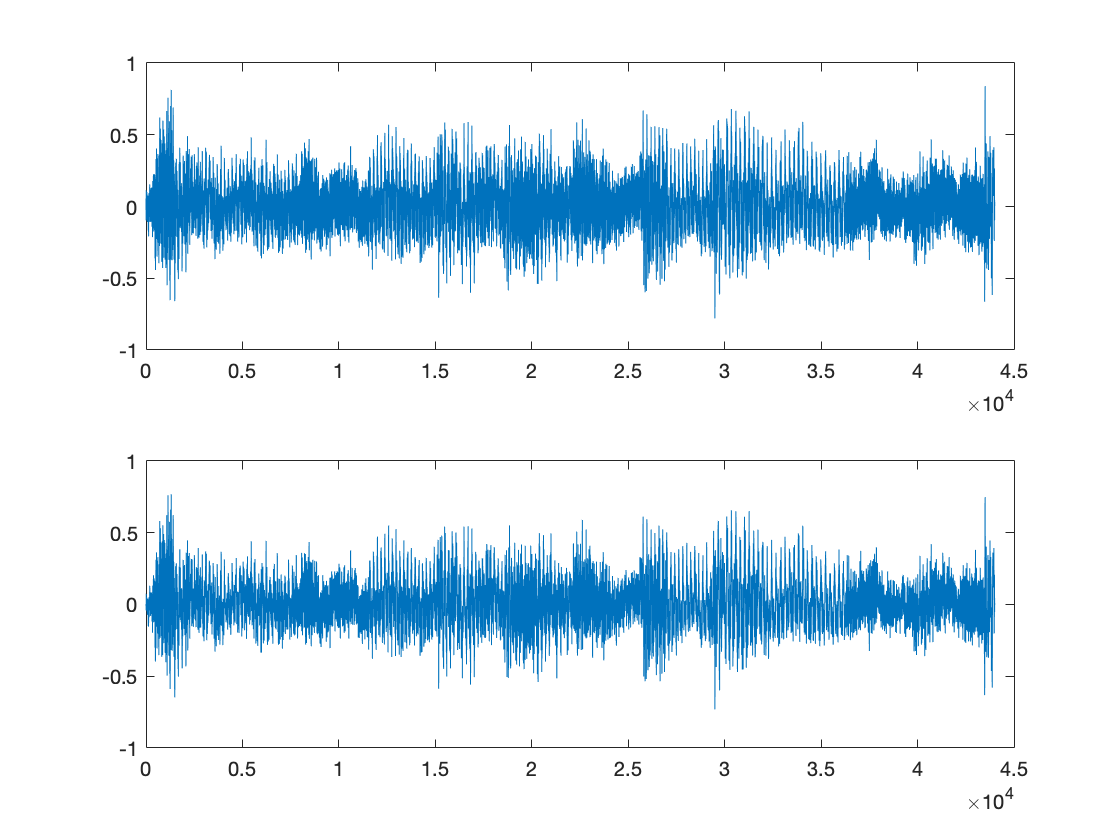


[a1,b1]=discreteWaveletTransform(v,fl,fh);
[a2,b2]=discreteWaveletTransform(a1,fl,fh);
[a3,b3]=discreteWaveletTransform(a2,fl,fh);

N=length(b1)+length(b3)+length(b3);

sigma=mad(b1,1)/0.6745;
lambda=sigma*sqrt(2*log(N));

b1s=softThresholding(b1,lambda);
b2s=softThresholding(b2,lambda);
b3s=softThresholding(b3,lambda);

%S=softThresholding(Cb,lambda);

a22 = invDaubechies1D(a3,b3s,fl,fh);
a11 = invDaubechies1D(a22,b2s,fl,fh);
rec_sig = invDaubechies1D(a11,b1s,fl,fh);
%rec_sig(rec_sig==0) = [];

rec_sig=rec_sig(1:n);

figure
subplot(211)
plot(f,v)
subplot(212)
plot(f,rec_sig);


audiowrite('cd3.wav',rec_sig,fs);


Question 7.4

clear
[z_noisy]=audioread('cd1.wav');
[x_clean]=audioread('cd2.wav');
[z_denoised]=audioread('cd3.wav');

L=length(x_clean)

L = 176400

%e_diff=zeros(1,L)

% for i=1:L
%    e_diff(i)=x_clean(i)-z_noisy(i);
%    e_diff_denoised(i)=x_clean(i)-z_denoised(i);
% end

e_diff=x_clean-z_noisy;
e_diff_denoised=x_clean-z_denoised;

suma_noise=sum(x_clean.^2)/sum(e_diff.^2);
suma_denoise=sum(x_clean.^2)/sum(e_diff_denoised.^2);

SNR1=10*log(suma_noise)/log(10)

SNR1 = 7.0777

SNR2=10*log(suma_denoise)/log(10)

SNR2 = 7.8557


r1 = snr(x_clean,e_diff)

r1 = 7.0777

r2 = snr(x_clean,e_diff_denoised)

r2 = 7.8557